% Load temperature data from txt.
Folder = "E:/MatlabWorkStation/temperatureprogressionexperiment/";
Files = dir(Folder);                % 获取文件夹路径下文件，结构体类型
Files = Files(~[Files.isdir]);      % 去掉本身和父文件夹，剩余的即为文件个数
FilesNum = length(Files);            % 获取文件个数
DataCell = cell(1,FilesNum);         % 创建数据存储元胞
XCell = cell(1,FilesNum);
pCell = cell(1,FilesNum);
TableColumnNames = {'pt1','pt2','pt3','pt4','pt5','pt6','pt7',...
                    'pst1','pst2','pst3','pst4','pst5','pst6','pst7',...
                    'pp1','pp2','pp3','pp4','pp5','pp6','pp7'};


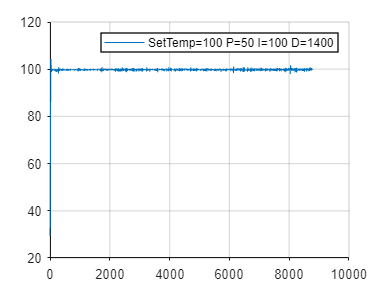

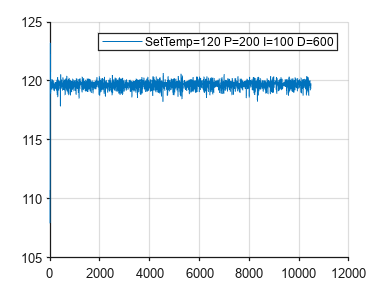

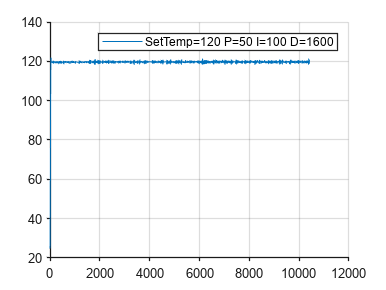

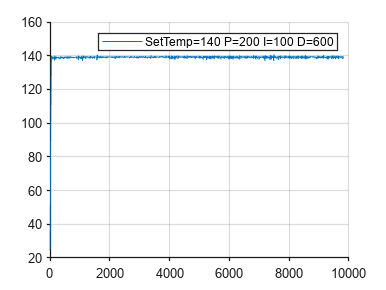

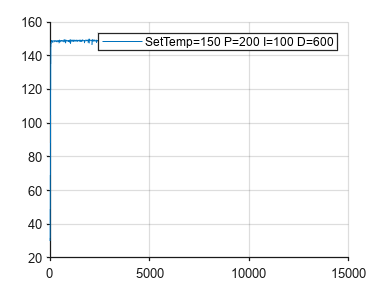

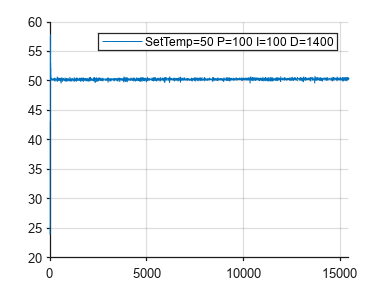

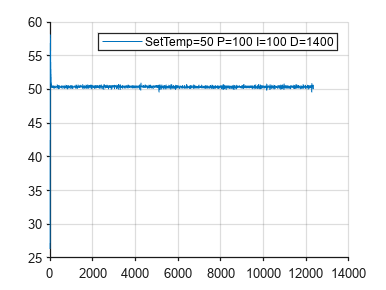

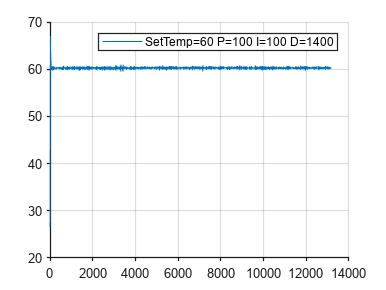

% 读取文件中温度有关数据
for i = 1:FilesNum
    filename = fullfile(Folder, Files(i).name);
    str = strsplit(Files(i).name,'_');
    DataCell{i} = readtable(filename);
    DataCell{i}.Properties.VariableNames = TableColumnNames;
    figure(i);
    XCell{i} = linspace(1,height(DataCell{i}),height(DataCell{i}));
    pCell{i} = plot(XCell{i}, ...
                    DataCell{i}.pt1, ...
                    'DisplayName',sprintf("SetTemp=%s P=%s I=%s D=%s",extractAfter(str{1},4),str{2},str{3},str{4}));
    set(gca,'Box','off', ...                                    % 边框开关
        'LineWidth',1, ...                                  % 线宽（非数据线）
        'XGrid','on','YGrid','on', ...                      % 网格开关
        'TickDir','out','TickLength',[0.01 0.01], ...       % 刻度调整，朝外、0.01
        'XMinorTick', 'off', 'YMinorTick', 'off', ...       % 小刻度开关
        'XColor', [.1 .1 .1],  'YColor', [.1 .1 .1]);       % 坐标轴颜色
    legend;
end

p = plot(XCell{1},DataCell{1}.pointtemp1);
set(gca,'Box','off', ...                                    % 边框开关
        'LineWidth',1, ...                                  % 线宽（非数据线）
        'XGrid','on','YGrid','on', ...                      % 网格开关
        'TickDir','out','TickLength',[0.01 0.01], ...       % 刻度调整，朝外、0.01
        'XMinorTick', 'off', 'YMinorTick', 'off', ...       % 小刻度开关
        'XColor', [.1 .1 .1],  'YColor', [.1 .1 .1]);       % 坐标轴颜色


